**Задание 1.1**

Представим систему W(z)=b/(z+a) при u(t)=sin(wt) как y'+ay=bsin(wt) <=> y'=-ay+bsin(wt)

clear()
load("C:\Users\vorko\OneDrive\Рабочий стол\Учеба\Учеба(финальный сем)\ident_lab2_v02.mat")
zad1

zad1 = struct with fields:
    a: 0.9300
    b: 2.8000
    w: 8.7900


a=zad1.a;
b=zad1.b;
w=zad1.w;
dT=0.1;
tMax=3;
T=(0:dT:tMax-dT)'; % Задаем дискретизацию
u=sin(w*T);
Y_(1)=0;

% Моделирование переходного процесса
for i=1:length(T)
    t=T(i);
     
    Y_(i+1)=a*Y_(i)+b*sin(w*t);
end

**Задание 1.2**

Используя следующаю формулу:

или ее дискретное представление:

где:

В нашем случае cистема представляет следующую форму:

тогда подставляя наши данные получается:

 y'=[-y sin(wt)]  [a; b]

Y1=Y_(2:length(Y_))';
Y0=Y_(1:length(Y_)-1)';

Y=Y1;
X=[-Y0 sin(w*T)]';

Проверим корреляцию между состояниями:

fprintf("Проверка на корреляцию:")

Проверка на корреляцию:

corr(X(1,:)', X(2,:)')

ans = 0.2929

Как видно из ответа, величины полностью коррелированы, следовательно не получится оценить каждый из параметров отдельно. Но для убедительности все же попробуем

**Задание 1.3**

G=1;
O=[0; 0]; 
for i=1:length(T)
    e=Y(i)-X(:, i)'*O;
    O=O+G*X(:, i)*e/(1+G*X(:, i)'*X(:, i));
end
O_first=O;

G=3;
O=[0; 0]; 
for i=1:length(T)
    e=Y(i)-X(:, i)'*O;
    O=O+G*X(:, i)*e/(1+G*X(:, i)'*X(:, i));
end
O_second=O;

G=10;
O=[0; 0]; 
for i=1:length(T)
    e=Y(i)-X(:, i)'*O;
    O=O+G*X(:, i)*e/(1+G*X(:, i)'*X(:, i));
end
O_third=O;

fprintf("Полученные значения параметров:")

Полученные значения параметров:

O_first'

ans =    -0.9277    2.7771


O_second'

ans =    -0.9299    2.7987


O_third'

ans =    -0.9300    2.8000


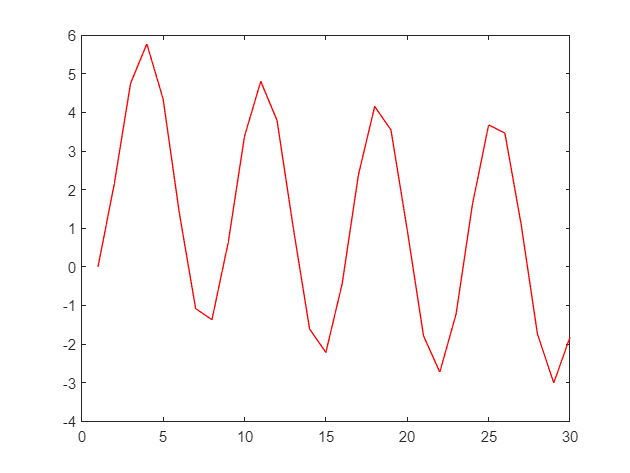



% ОЧЕНЬ ВАЖНАЯ отладочная штука
plot(Y1(1:30), 'blue')
hold on
Y_hat=X'*O;
plot(Y_hat(1:30), 'red')
hold off

Все 3 модели хорошо справились с задачей, из найденных параметров можно сделать вывод, что для больший значений гамма градиентный спуск оказывается быстрее

Также последний график доказывает, что подобранные параметры позваляют полностью восстановить параметры системы

**Задание 1.4**

G=0.05;
O=[0; 0]; 
for i=1:length(T)
    e=Y(i)-X(:, i)'*O;
    O=O+G*X(:, i)*e;
end
O_first=O;

G=10;
O=[0; 0]; 
for i=1:length(T)
    e=Y(i)-X(:, i)'*O;
    O=O+G*X(:, i)*e;
end
O_second=O;

fprintf("Полученные значения параметров:")

Полученные значения параметров:

O_first'

ans =    -0.7631    1.4653


O_second'

ans = 1.0e+43 *

    1.4109    0.1718


Как видно из результатов, упрощенная модель градиентного спуска справилась с задачей только при малом гамма, при большом модель оказалась неустойчивой

**Задание 2.1**

Представим систему W(z)=b/(z^2+a1z+a2) при u(t)=sin(wt) как y''+a1y'+a2y=bsin(wt) <=> y''=-a1y'-a2y+bsin(wt)

clear()
load("C:\Users\vorko\OneDrive\Рабочий стол\Учеба\Учеба(финальный сем)\ident_lab2_v02.mat")

zad2

zad2 = struct with fields:
    a2: 0.9021
    a1: -1.9000
     b: 2.6000
     w: 47.1200


a1=zad2.a1;
a2=zad2.a2;
b=zad2.b;
w=50; %для упрощения проверки неисчизающего аозбуждения округлим частоту
dT=0.005;
tMax=20;
T=(0:dT:tMax-dT)'; % Задаем дискретизацию
Y_(1)=0;
Y_(2)=0;
% Моделирование переходного процесса
for i=1:length(T)
    t=T(i);
    Y_(i+2)=-a1*Y_(i+1)-a2*Y_(i)+b*sin(w*t);
end

**Задание 2.2**

Y2=Y_(3:length(Y_))';
Y1=Y_(2:length(Y_)-1)';
Y0=Y_(1:length(Y_)-2)';
% plot(T, Y2)

Y=Y2;
X=[-Y1 -Y0 sin(w*T)]';

**Задание 2.3**

G=1;
O=[0; 0; 0];

for i=1:length(T)
    e=Y(i)-X(:, i)'*O;
    O=O+G*X(:, i)*e/(1+G*X(:, i)'*X(:, i));
    Og(i, :)=O;
%     eg(i)=e;
end
O

O =    -1.9181
    0.9488
    1.3590


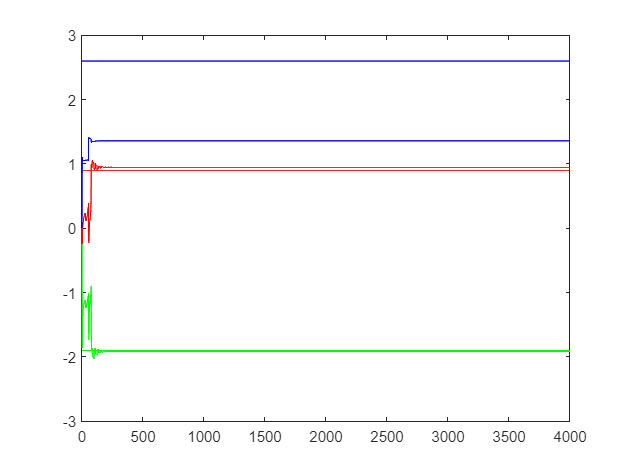

% plot(eg, 'yellow')
plot(Og(:, 1), 'green')
hold on
plot(a1*ones(length(T)), 'green')
hold on
plot(Og(:, 2), 'red')
hold on
plot(a2*ones(length(T)), 'red')
hold on
plot(Og(:, 3), 'blue')
hold on
plot(b*ones(length(T)), 'blue')
hold off

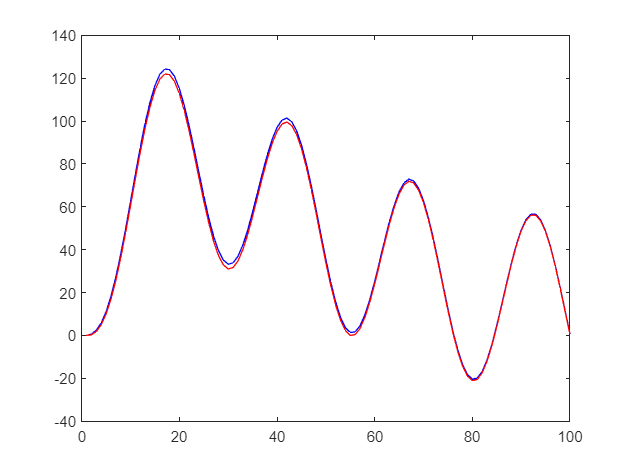

% ОЧЕНЬ ВАЖНАЯ отладочная штука
plot(Y2(1:100), 'blue')
hold on
Y_hat=X'*O;
plot(Y_hat(1:100), 'red')
hold off

**Проверки на неисчезающее возбуждение:**

fprintf("интеграл по 1/4 периода")

интеграл по 1/4 периода

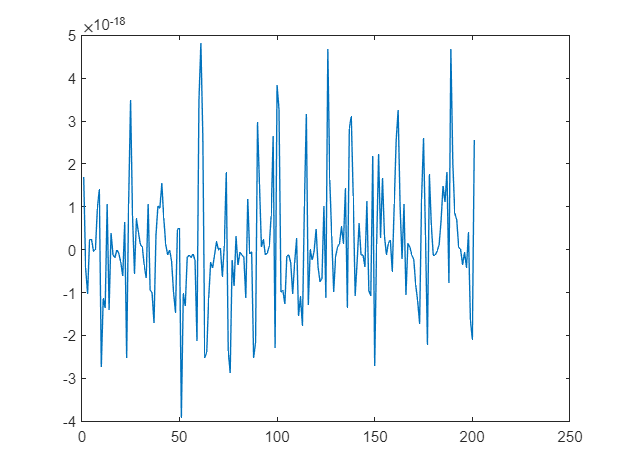

step=2;
for i=1:length(X(1, :))-step
    SQRT1=(X(:, i+0)*X(:, i+0)'+X(:, i+1)*X(:, i+1)')/2*dT;
    SQRT2=(X(:, i+1)*X(:, i+1)'+X(:, i+2)*X(:, i+2)')/2*dT;
    DET2(i)=det(SQRT1+SQRT2);  
end
plot(DET2(1000:1200))

fprintf("интеграл по 3/8 периода")

интеграл по 3/8 периода

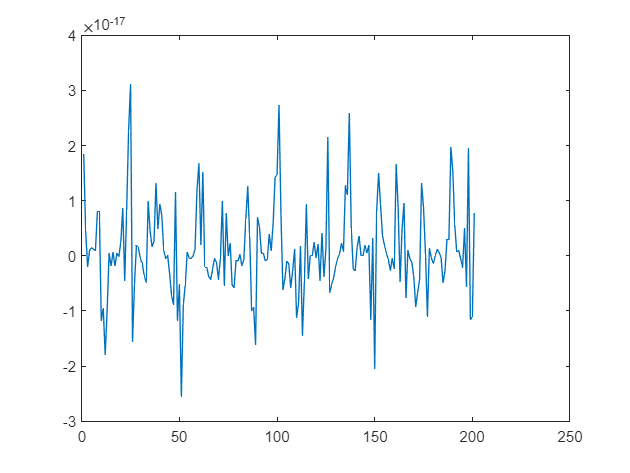

step=3;
for i=1:length(X(1, :))-step
    SQRT1=(X(:, i+0)*X(:, i+0)'+X(:, i+1)*X(:, i+1)')/2*dT;
    SQRT2=(X(:, i+1)*X(:, i+1)'+X(:, i+2)*X(:, i+2)')/2*dT;
    SQRT3=(X(:, i+2)*X(:, i+2)'+X(:, i+3)*X(:, i+3)')/2*dT;
    DET3(i)=det(SQRT1+SQRT2+SQRT3);  
end
plot(DET3(1000:1200))

fprintf("интеграл по 1/2 периода")

интеграл по 1/2 периода

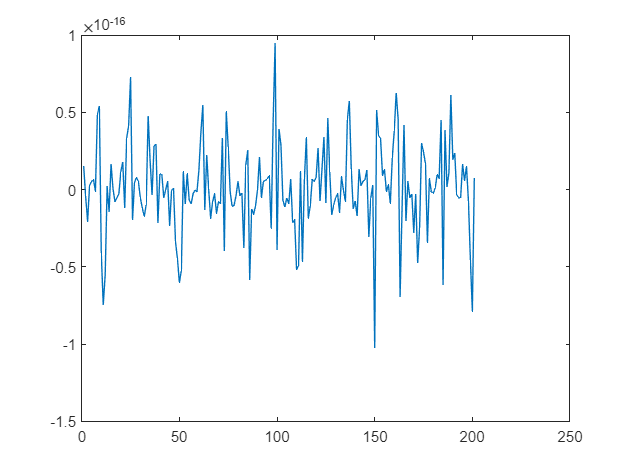

step=4;
for i=1:length(X(1, :))-step
    SQRT1=(X(:, i+0)*X(:, i+0)'+X(:, i+1)*X(:, i+1)')/2*dT;
    SQRT2=(X(:, i+1)*X(:, i+1)'+X(:, i+2)*X(:, i+2)')/2*dT;
    SQRT3=(X(:, i+2)*X(:, i+2)'+X(:, i+3)*X(:, i+3)')/2*dT;
    SQRT4=(X(:, i+3)*X(:, i+3)'+X(:, i+4)*X(:, i+4)')/2*dT;
    DET4(i)=det(SQRT1+SQRT2+SQRT3+SQRT4);  
end
plot(DET4(1000:1200))

Неизвестные параметры найдены верно

Последний график доказывает, что подобранные параметры позваляют полностью восстановить параметры системы

**Задание 2.4**

clear()
load("C:\Users\vorko\OneDrive\Рабочий стол\Учеба\Учеба(финальный сем)\ident_lab2_v02.mat")

zad2

zad2 = struct with fields:
    a2: 0.9021
    a1: -1.9000
     b: 2.6000
     w: 47.1200


a1=zad2.a1;
a2=zad2.a2;
b=zad2.b;
w=50; % для упрощения проверки неисчизающего аозбуждения округлим частоту
dT=0.005;
tMax=20;
T=(0:dT:tMax-dT)'; % Задаем дискретизацию
u=sin(w*T);
Y_(1)=0;
Y_(2)=0;
% Моделирование переходного процесса
for i=1:length(T)
    t=T(i);
    Y_(i+2)=-a1*Y_(i+1)-a2*Y_(i)+b*(sin(w*t)+0.2*sin(0.5*w*t));
end

Y2=Y_(3:length(Y_))';
Y1=Y_(2:length(Y_)-1)';
Y0=Y_(1:length(Y_)-2)';
% plot(T, Y2)

Y=Y2;
X=[-Y1 -Y0 sin(w*T)+0.2*sin(0.5*w*T)]';

G=1;
O=[0; 0; 0];

for i=1:length(T)
    e=Y(i)-X(:, i)'*O;
    O=O+G*X(:, i)*e/(1+G*X(:, i)'*X(:, i));
    Og(i, :)=O;
%     eg(i)=e;
end
O

O =    -1.8904
    0.8993
    2.4523


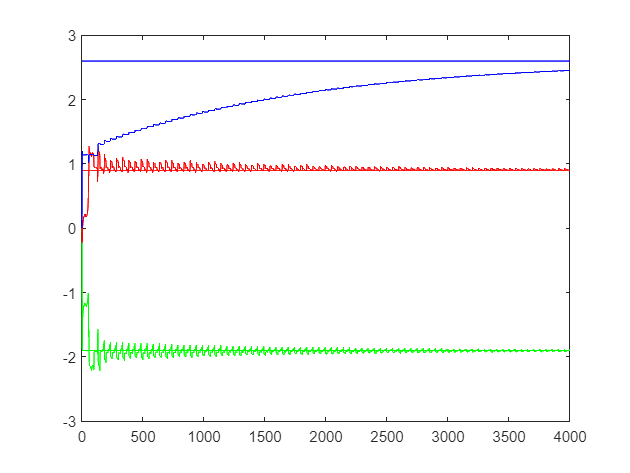

% plot(eg, 'yellow')
plot(Og(:, 1), 'green')
hold on
plot(a1*ones(length(T)), 'green')
hold on
plot(Og(:, 2), 'red')
hold on
plot(a2*ones(length(T)), 'red')
hold on
plot(Og(:, 3), 'blue')
hold on
plot(b*ones(length(T)), 'blue')
hold off

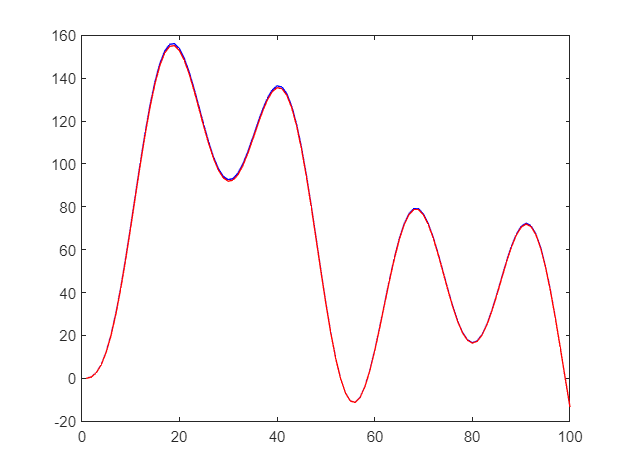

% ОЧЕНЬ ВАЖНАЯ отладочная штука
plot(Y2(1:100), 'blue')
hold on
Y_hat=X'*O;
plot(Y_hat(1:100), 'red')
hold off

**Проверки на неисчезающее возбуждение:**

fprintf("интеграл по 1/4 периода")

интеграл по 1/4 периода

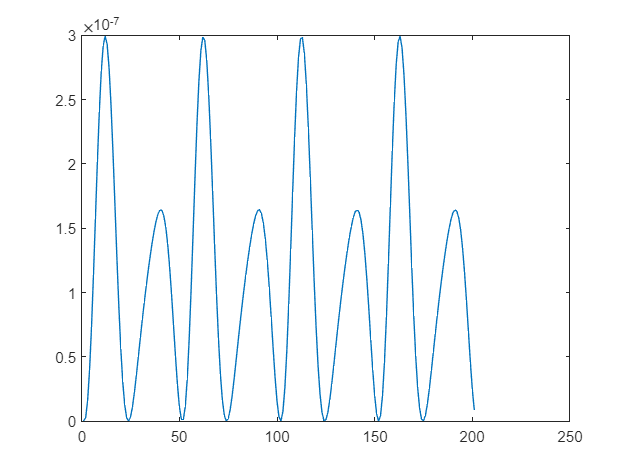

step=2;
for i=1:length(X(1, :))-step
    SQRT1=(X(:, i+0)*X(:, i+0)'+X(:, i+1)*X(:, i+1)')/2*dT;
    SQRT2=(X(:, i+1)*X(:, i+1)'+X(:, i+2)*X(:, i+2)')/2*dT;
    DET2(i)=det(SQRT1+SQRT2);  
end
plot(DET2(1000:1200))

fprintf("интеграл по 3/8 периода")

интеграл по 3/8 периода

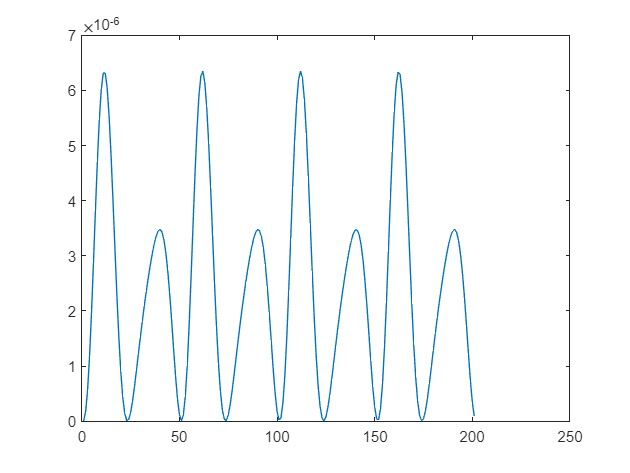

step=3;
for i=1:length(X(1, :))-step
    SQRT1=(X(:, i+0)*X(:, i+0)'+X(:, i+1)*X(:, i+1)')/2*dT;
    SQRT2=(X(:, i+1)*X(:, i+1)'+X(:, i+2)*X(:, i+2)')/2*dT;
    SQRT3=(X(:, i+2)*X(:, i+2)'+X(:, i+3)*X(:, i+3)')/2*dT;
    DET3(i)=det(SQRT1+SQRT2+SQRT3);  
end
plot(DET3(1000:1200))

fprintf("интеграл по 1/2 периода")

интеграл по 1/2 периода

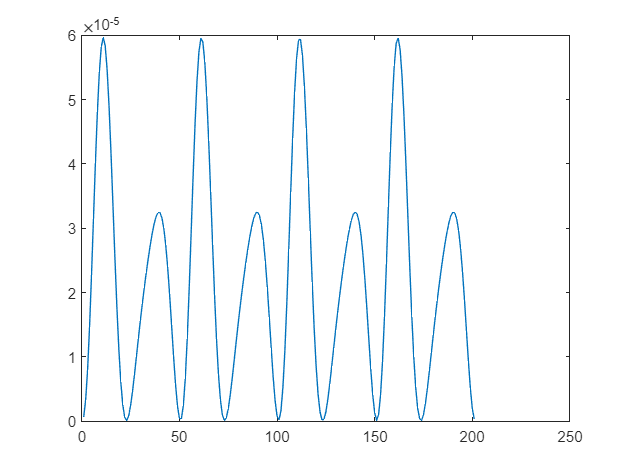

step=4;
for i=1:length(X(1, :))-step
    SQRT1=(X(:, i+0)*X(:, i+0)'+X(:, i+1)*X(:, i+1)')/2*dT;
    SQRT2=(X(:, i+1)*X(:, i+1)'+X(:, i+2)*X(:, i+2)')/2*dT;
    SQRT3=(X(:, i+2)*X(:, i+2)'+X(:, i+3)*X(:, i+3)')/2*dT;
    SQRT4=(X(:, i+3)*X(:, i+3)'+X(:, i+4)*X(:, i+4)')/2*dT;
    DET4(i)=det(SQRT1+SQRT2+SQRT3+SQRT4);  
end
plot(DET4(1000:1200))

Точность найденных параметров системы немного выше в случае подачи суммы синусоидальных сигналов с разной частотой

**Задание 3.1**

clear()
load("C:\Users\vorko\OneDrive\Рабочий стол\Учеба\Учеба(финальный сем)\ident_lab2_v02.mat")


zad3

zad3 = struct with fields:
    a: 1.2000
    b: 2.9000
    w: 6.9100


a=zad3.a;
b=zad3.b;
w=zad3.w;

dT=0.001;
maxT=20;
out = sim('C:\Users\vorko\OneDrive\Рабочий стол\Учеба\Учеба(финальный сем)\Identification_Lab_23.slx', maxT);


Yreal=out.y.Data;
Yreal_=out.y_.Data;1

ans = 1

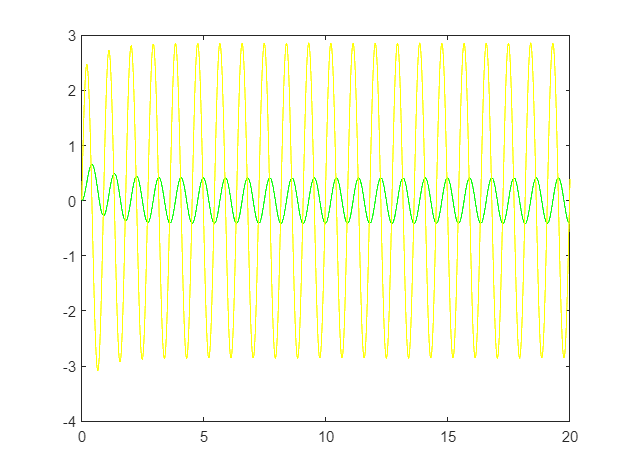

T=(0:dT:maxT)';

plot(T, Yreal, 'green')
hold on
plot(T, Yreal_, 'yellow')
hold off


Y=Yreal_;
X=[-Yreal sin(w*T)]';

fprintf("Проверка на корреляцию:")

Проверка на корреляцию:

corr(X(1,:)', X(2,:)')

ans = -0.1816

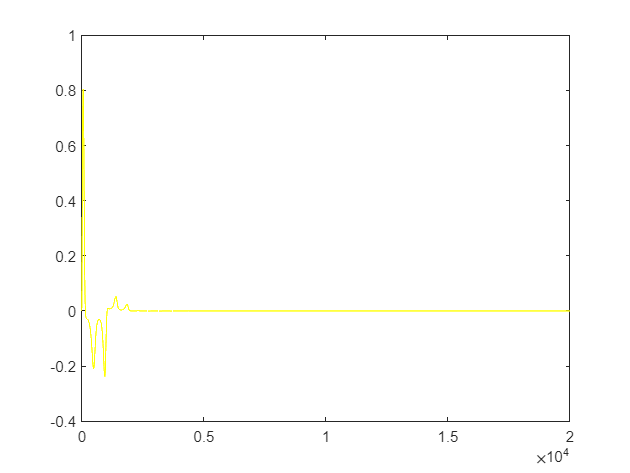


G=0.1;
O=[0; 0]; 
for i=1:length(T)-1/w/2*dT
    e=Y(i)-X(:, i)'*O;
    O=O+G*X(:, i)*e;
    Og(i, :)=O;
    eg(i)=e;
end
plot(eg, 'yellow')

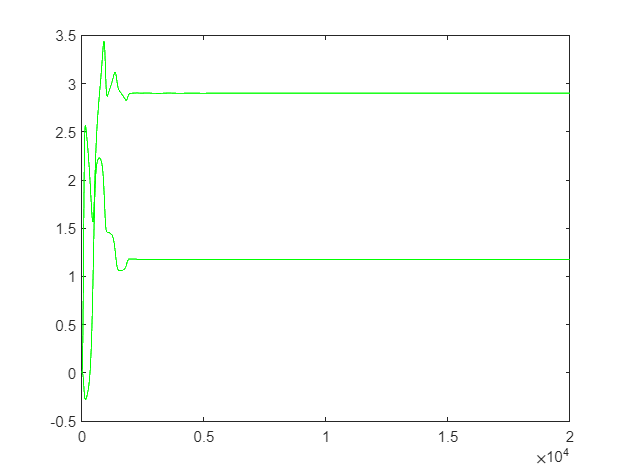

plot(Og, 'green')

O

O =     1.1761
    2.9000


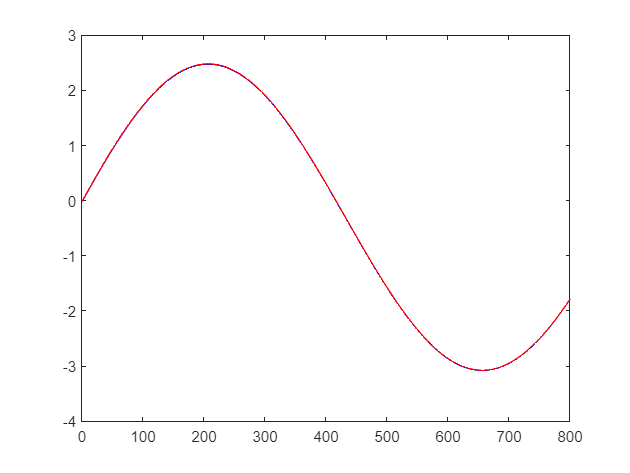


% ОЧЕНЬ ВАЖНАЯ отладочная штука
plot(Yreal_(1:800), 'blue')
hold on
Y_hat=X'*O;
plot(Y_hat(1:800), 'red')
hold off

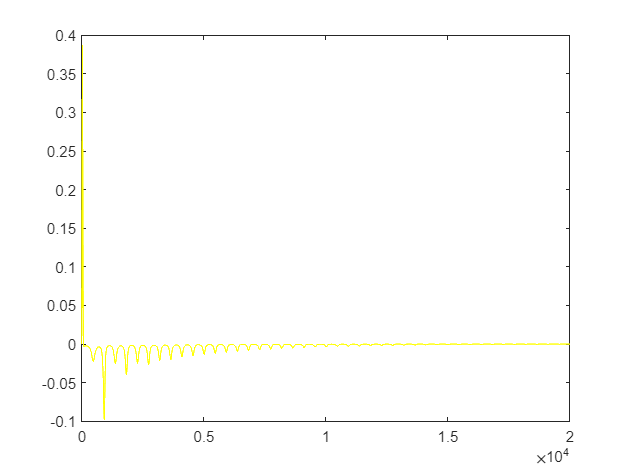

G=1;
O=[0; 0]; 
for i=1:length(T)-1/w/2*dT
    e=Y(i)-X(:, i)'*O;
    O=O+G*X(:, i)*e;
    Og(i, :)=O;
    eg(i)=e;
end
plot(eg, 'yellow')

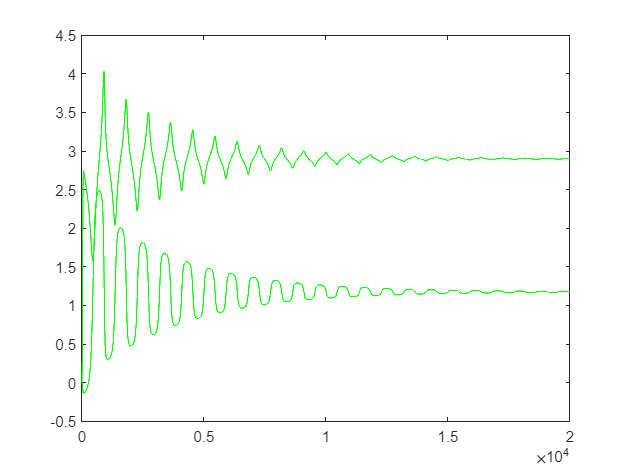

plot(Og, 'green')

O

O =     1.1771
    2.9057


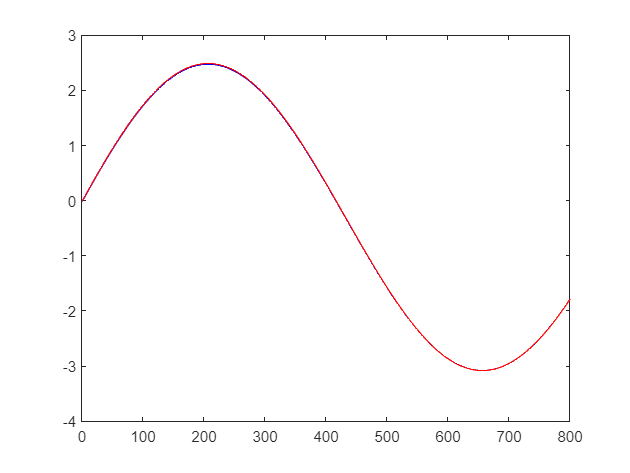


% ОЧЕНЬ ВАЖНАЯ отладочная штука
plot(Yreal_(1:800), 'blue')
hold on
Y_hat=X'*O;
plot(Y_hat(1:800), 'red')
hold off

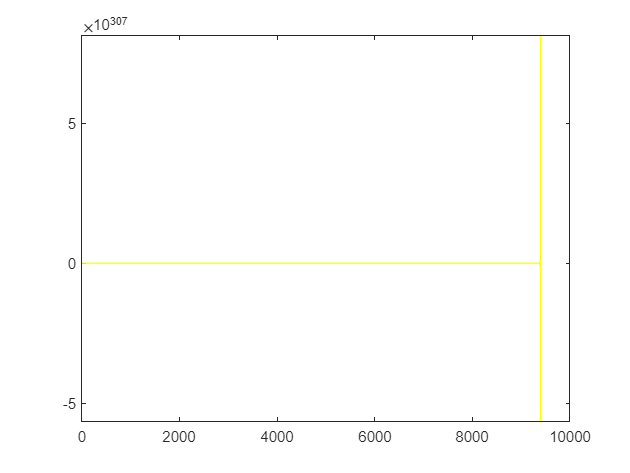


G=3;
O=[0; 0]; 
for i=1:length(T)-1/w/2*dT
    e=Y(i)-X(:, i)'*O;
    O=O+G*X(:, i)*e;
    Og(i, :)=O;
    eg(i)=e;
end
plot(eg, 'yellow')

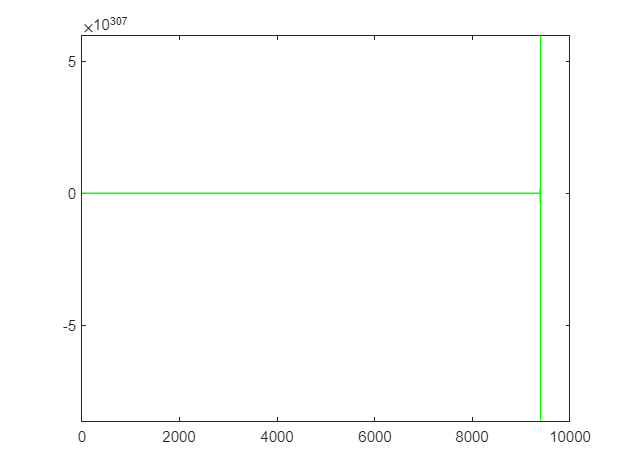

plot(Og, 'green')

O

O =    NaN
   NaN


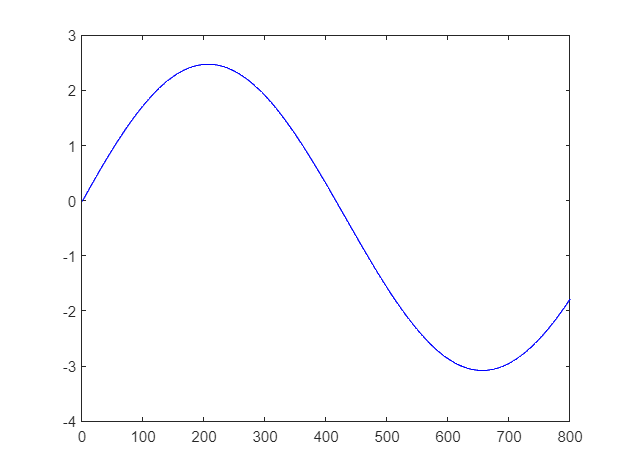


% ОЧЕНЬ ВАЖНАЯ отладочная штука
plot(Yreal_(1:800), 'blue')
hold on
Y_hat=X'*O;
plot(Y_hat(1:800), 'red')
hold off

Удалось найти абсолютно точно параметры системы, также совпал и конечный график. Это говорит о том, что градиентный поиск реализован верно